# A comparison between *D*-optimal and model-based DoE

Iván Blázquez Arenas, Pablo Carbonell, Irene Otero-Muras

## ODoE Results for second case of study

clc;clear all;close all;

%Functions needed
addpath Model_Cases\
addpath Experimentation\
addpath ODoE_functions\
addpath Parameter_Estimation\


## Input parameters

%% INPUTS %%

%COMMON INPUTS

% - Max number of experiments

n_max = 30;

% - Number of initial valid design seeds

seeds = 100;

% - Design Space

Lb = 0.1;
Ub = 3e5;

% - Number of factors/dimension of support point

k = 1;

%ODoE INPUTS

% - Min number of experiments (depends on model structure, number of parameters plus one)

n_min_lin = (k + 1) + 1;
n_min_inter = (k + 1) + k*(k - 1)/2 + 1;
n_min_quad = (2*k + 1) + k*(k - 1)/2 + 1;

% - Levels considered per factor

levels_ODoE = 5;

% - Max iterations in CE algorithm

Max_iter = 100;

% EXPERIMENT SIMULATION INPUTS

% - Experiment parameters

p_exp = [1e-8 1e3];

% - Experiment model

model_experiment = @(x)Model_case_2(x,p_exp); %PC

% - Experiment rounds

n_rounds = 100;

% - Max.Relative Error added (+/- x%)

max_rel_error = 10;

% MODEL VALIDATION

% - Number of random points to validate

n_exp_val = 100;



## Response simulation 

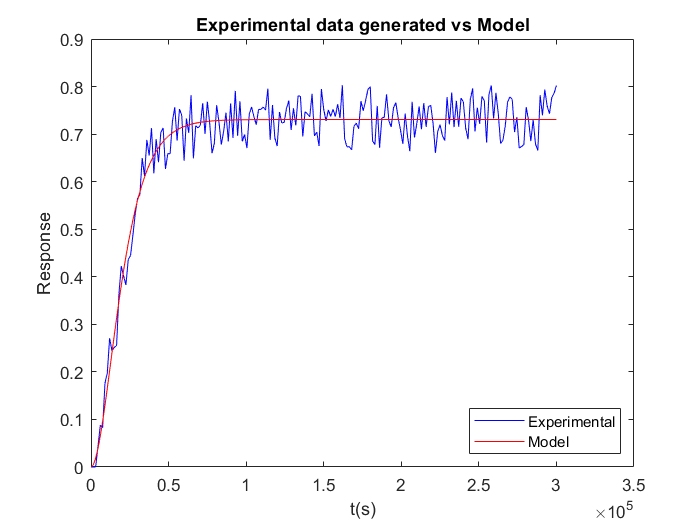

t = [0.1:1500:3e5 + 0.1];
y1 = Experiment_Simulation2(model_experiment, t', max_rel_error, 1);
y2 = Experiment_Simulation2(model_experiment, t', 0, 1);
figure(1)
plot(t,y1,'b')
hold on
plot(t,y2,'r')
hold off
title("Experimental data generated vs Model")
xlabel("t(s)")
ylabel("Response")
legend('Experimental','Model','Location','southeast')

## **Preallocating the results**

%% PROCESS %%

% - Cell structure for results

n_cases_lin = (n_max - n_min_lin) + 1;        % Number of cases for linear model
n_cases_inter = (n_max - n_min_inter) + 1;    % Number of cases for main effects and interactions model
n_cases_quad = (n_max - n_min_quad) + 1;      % Number of cases for quadratic model

results_ODoE_CE_lin = cell(n_cases_lin, 9);         % Selecting the best of all computed, linear model
results_ODoE_CE_inter = cell(n_cases_inter, 9);     % Selecting the best of all computed, with interactions model
results_ODoE_CE_quad = cell(n_cases_quad, 9);       % Selecting the best of all computed, with quadratic model

results_ODoE_GA_lin = cell(n_cases_lin, 9);         % Using genetic algorythm, linear model
results_ODoE_GA_inter = cell(n_cases_inter, 9);     % Using genetic algorythm, with interactions model
results_ODoE_GA_quad = cell(n_cases_quad, 9);       % Using genetic algorythm, with quadratic model


## Optimal design of experiments with ODoE:

- Coordinate Exchange, linear model

tic

index = 1;

for n = n_min_lin:n_max
    
    n
    [D_opt,~,Deff_max,~,~,~,~] = Dopt_CE(n,k,levels_ODoE,'linear',Lb,Ub,Max_iter,seeds);
    results_ODoE_CE_lin(index,1) = {n};
    results_ODoE_CE_lin(index,2) = {D_opt};
    results_ODoE_CE_lin(index,3) = {Deff_max};
    index = index + 1;
    
end

n = 3

n = 4

DISEÑO ORTOGONAL ALCANZADO


n = 5

n = 6

DISEÑO ORTOGONAL ALCANZADO


n = 7

n = 8

DISEÑO ORTOGONAL ALCANZADO


n = 9

n = 10

DISEÑO ORTOGONAL ALCANZADO


n = 11

n = 12

DISEÑO ORTOGONAL ALCANZADO


n = 13

n = 14

DISEÑO ORTOGONAL ALCANZADO


n = 15

n = 16

DISEÑO ORTOGONAL ALCANZADO


n = 17

n = 18

DISEÑO ORTOGONAL ALCANZADO


n = 19

n = 20

DISEÑO ORTOGONAL ALCANZADO


n = 21

n = 22

DISEÑO ORTOGONAL ALCANZADO


n = 23

n = 24

DISEÑO ORTOGONAL ALCANZADO


n = 25

n = 26

DISEÑO ORTOGONAL ALCANZADO


n = 27

n = 28

DISEÑO ORTOGONAL ALCANZADO


n = 29

n = 30

DISEÑO ORTOGONAL ALCANZADO



t_ODoE_CE_lin = toc

t_ODoE_CE_lin = 0.0062

- Coordinate Exchange, main effects with interactions model

tic

index = 1;

for n = n_min_inter:n_max
    
    n
    [D_opt,~,Deff_max,~,~,~,~] = Dopt_CE(n,k,levels_ODoE,'interactions',Lb,Ub,Max_iter,seeds);
    results_ODoE_CE_inter(index,1) = {n};
    results_ODoE_CE_inter(index,2) = {D_opt};
    results_ODoE_CE_inter(index,3) = {Deff_max};
    index = index + 1;
    
end

n = 3

n = 4

DISEÑO ORTOGONAL ALCANZADO


n = 5

n = 6

DISEÑO ORTOGONAL ALCANZADO


n = 7

n = 8

DISEÑO ORTOGONAL ALCANZADO


n = 9

n = 10

DISEÑO ORTOGONAL ALCANZADO


n = 11

n = 12

DISEÑO ORTOGONAL ALCANZADO


n = 13

n = 14

DISEÑO ORTOGONAL ALCANZADO


n = 15

n = 16

DISEÑO ORTOGONAL ALCANZADO


n = 17

n = 18

DISEÑO ORTOGONAL ALCANZADO


n = 19

n = 20

DISEÑO ORTOGONAL ALCANZADO


n = 21

n = 22

DISEÑO ORTOGONAL ALCANZADO


n = 23

n = 24

DISEÑO ORTOGONAL ALCANZADO


n = 25

n = 26

DISEÑO ORTOGONAL ALCANZADO


n = 27

n = 28

DISEÑO ORTOGONAL ALCANZADO


n = 29

n = 30

DISEÑO ORTOGONAL ALCANZADO



t_ODoE_CE_inter = toc

t_ODoE_CE_inter = 0.0043

- Coordinate Exchange, quadratic model

tic

index = 1;

for n = n_min_quad:n_max
    
    n
    [D_opt,~,Deff_max,~,~,~,~] = Dopt_CE(n,k,levels_ODoE,'quadratic',Lb,Ub,Max_iter,seeds);
    results_ODoE_CE_quad(index,1) = {n};
    results_ODoE_CE_quad(index,2) = {D_opt};
    results_ODoE_CE_quad(index,3) = {Deff_max};
    index = index + 1;
    
end

n = 4

n = 5

n = 6

n = 7

n = 8

n = 9

n = 10

n = 11

n = 12

n = 13

n = 14

n = 15

n = 16

n = 17

n = 18

n = 19

n = 20

n = 21

n = 22

n = 23

n = 24

n = 25

n = 26

n = 27

n = 28

n = 29

n = 30


t_ODoE_CE_quad = toc

t_ODoE_CE_quad = 0.1012

- Genetic Algorithm, linear model

tic

index = 1;

for n = n_min_lin:n_max
    
    n
    [D_opt,~,Deff_max,~,~,~,~] = Dopt_GA(n,k,levels_ODoE,'linear',Lb,Ub,seeds);
    results_ODoE_GA_lin(index,1) = {n};
    results_ODoE_GA_lin(index,2) = {D_opt};
    results_ODoE_GA_lin(index,3) = {Deff_max};
    index = index + 1;
    
end

n = 3

n = 4

DISEÑO ORTOGONAL ALCANZADO


n = 5

n = 6

DISEÑO ORTOGONAL ALCANZADO


n = 7

n = 8

DISEÑO ORTOGONAL ALCANZADO


n = 9

n = 10

DISEÑO ORTOGONAL ALCANZADO


n = 11

n = 12

DISEÑO ORTOGONAL ALCANZADO


n = 13

n = 14

DISEÑO ORTOGONAL ALCANZADO


n = 15

n = 16

DISEÑO ORTOGONAL ALCANZADO


n = 17

n = 18

DISEÑO ORTOGONAL ALCANZADO


n = 19

n = 20

DISEÑO ORTOGONAL ALCANZADO


n = 21

n = 22

DISEÑO ORTOGONAL ALCANZADO


n = 23

n = 24

DISEÑO ORTOGONAL ALCANZADO


n = 25

n = 26

DISEÑO ORTOGONAL ALCANZADO


n = 27

n = 28

DISEÑO ORTOGONAL ALCANZADO


n = 29

n = 30

DISEÑO ORTOGONAL ALCANZADO



t_ODoE_GA_lin = toc

t_ODoE_GA_lin = 354.0727

- Genetic Algorithm, main effects with interactions model

tic

index = 1;

for n = n_min_inter:n_max
    
    n
    [D_opt,~,Deff_max,~,~,~,~] = Dopt_GA(n,k,levels_ODoE,'interactions',Lb,Ub,seeds);
    results_ODoE_GA_inter(index,1) = {n};
    results_ODoE_GA_inter(index,2) = {D_opt};
    results_ODoE_GA_inter(index,3) = {Deff_max};
    index = index + 1;
    
end

n = 3

n = 4

DISEÑO ORTOGONAL ALCANZADO


n = 5

n = 6

DISEÑO ORTOGONAL ALCANZADO


n = 7

n = 8

DISEÑO ORTOGONAL ALCANZADO


n = 9

n = 10

DISEÑO ORTOGONAL ALCANZADO


n = 11

n = 12

DISEÑO ORTOGONAL ALCANZADO


n = 13

n = 14

DISEÑO ORTOGONAL ALCANZADO


n = 15

n = 16

DISEÑO ORTOGONAL ALCANZADO


n = 17

n = 18

DISEÑO ORTOGONAL ALCANZADO


n = 19

n = 20

DISEÑO ORTOGONAL ALCANZADO


n = 21

n = 22

DISEÑO ORTOGONAL ALCANZADO


n = 23

n = 24

DISEÑO ORTOGONAL ALCANZADO


n = 25

n = 26

DISEÑO ORTOGONAL ALCANZADO


n = 27

n = 28

DISEÑO ORTOGONAL ALCANZADO


n = 29

n = 30

DISEÑO ORTOGONAL ALCANZADO



t_ODoE_GA_inter = toc

t_ODoE_GA_inter = 359.7077

- Using a genetic Algorithm, quadratic model

tic

index = 1;

for n = n_min_quad:n_max
    
    n
    [D_opt,~,Deff_max,~,~,~,~] = Dopt_GA(n,k,levels_ODoE,'quadratic',Lb,Ub,seeds);
    results_ODoE_GA_quad(index,1) = {n};
    results_ODoE_GA_quad(index,2) = {D_opt};
    results_ODoE_GA_quad(index,3) = {Deff_max};
    index = index + 1;
    
end

n = 4

n = 5

n = 6

n = 7

n = 8

n = 9

n = 10

n = 11

n = 12

n = 13

n = 14

n = 15

n = 16

n = 17

n = 18

n = 19

n = 20

n = 21

n = 22

n = 23

n = 24

n = 25

n = 26

n = 27

n = 28

n = 29

n = 30


t_ODoE_GA_quad = toc

t_ODoE_GA_quad = 1.1529e+03

### *Plots:*

- Linear model

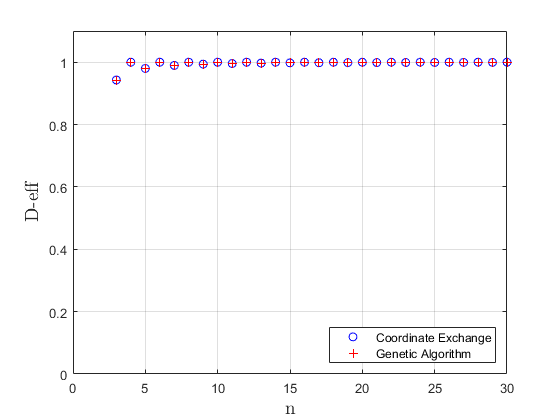

Deff_max_CE_lin = zeros(1, n_cases_lin);
Deff_max_GA_lin = zeros(1, n_cases_lin);
number_exp = n_min_lin:n_max;

for c = 1:n_cases_lin
    
    Deff_max_CE_lin(c) = results_ODoE_CE_lin{c,3};
    Deff_max_GA_lin(c) = results_ODoE_GA_lin{c,3};
    
end

figure(2)
plot(number_exp,Deff_max_CE_lin,'bo')
hold on
plot(number_exp,Deff_max_GA_lin,'r+')
hold off
ylim([0 1.1])
%title("Max D-efficiency per number of experiments, linear model",'Interpreter','latex','FontWeight','bold','FontSize',14)
xlabel("n",'Interpreter','latex','FontWeight','bold','FontSize',14)
ylabel("D-eff",'Interpreter','latex','FontWeight','bold','FontSize',14)
grid on
legend('Coordinate Exchange','Genetic Algorithm','Location','southeast')

- Main effects model with interactions

Deff_max_CE_inter = zeros(1, n_cases_inter);
Deff_max_GA_inter = zeros(1, n_cases_inter);
number_exp = n_min_inter:n_max;

for c = 1:n_cases_inter
    
    Deff_max_CE_inter(c) = results_ODoE_CE_inter{c,3};
    Deff_max_GA_inter(c) = results_ODoE_GA_inter{c,3};
    
end

figure(3)
plot(number_exp,Deff_max_CE_inter,'bo')
hold on
plot(number_exp,Deff_max_GA_inter,'r+')
hold off
ylim([0 1.1])
%title("Max D-efficiency per number of experiments, main effects with interactions model",'Interpreter','latex','FontWeight','bold','FontSize',10)
xlabel("n",'Interpreter','latex','FontWeight','bold','FontSize',14)
ylabel("D-eff",'Interpreter','latex','FontWeight','bold','FontSize',14)
grid on
legend('Coordinate Exchange','Genetic Algorithm','Location','southeast')

- Quadratic model

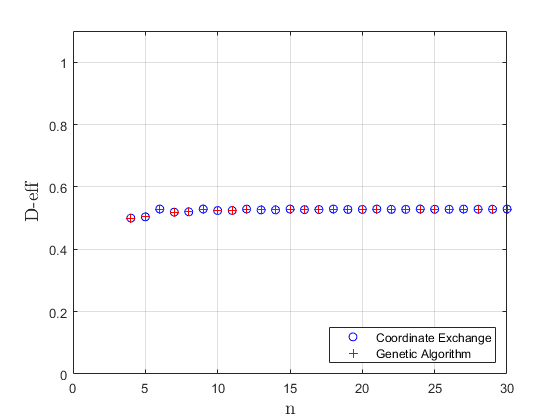

Deff_max_CE_quad = zeros(1, n_cases_quad);
Deff_max_GA_quad = zeros(1, n_cases_quad);
number_exp = n_min_quad:n_max;

for c = 1:n_cases_quad
    
    Deff_max_CE_quad(c) = results_ODoE_CE_quad{c,3};
    Deff_max_GA_quad(c) = results_ODoE_GA_quad{c,3};
    
end

figure(4)
plot(number_exp,Deff_max_CE_quad,'bo')
hold on
plot(number_exp,Deff_max_GA_quad,'r+')
hold off
ylim([0 1.1])
%title("Max D-efficiency per number of experiments, quadratic model",'Interpreter','latex','FontWeight','bold','FontSize',14)
xlabel("n",'Interpreter','latex','FontWeight','bold','FontSize',14)
ylabel("D-eff",'Interpreter','latex','FontWeight','bold','FontSize',14)
grid on
legend('Coordinate Exchange','Genetic Algorithm','Location','southeast')

## Simulating the experiments for ODoE designs

- Linear Model

for index = 1:n_cases_lin
      
    results = Experiment_Simulation2(model_experiment, results_ODoE_CE_lin{index,2}, max_rel_error, n_rounds);
    results_ODoE_CE_lin(index,4) = {results};
    
    results = Experiment_Simulation2(model_experiment, results_ODoE_GA_lin{index,2}, max_rel_error, n_rounds);
    results_ODoE_GA_lin(index,4) = {results};
    
end


- Main effects with interactions model

for index = 1:n_cases_inter
    
    results = Experiment_Simulation2(model_experiment, results_ODoE_CE_inter{index,2}, max_rel_error, n_rounds);
    results_ODoE_CE_inter(index,4) = {results};
    
    results = Experiment_Simulation2(model_experiment, results_ODoE_GA_inter{index,2}, max_rel_error, n_rounds);
    results_ODoE_GA_inter(index,4) = {results};
    
end


- Quadratic model

for index = 1:n_cases_quad
    
    results = Experiment_Simulation2(model_experiment, results_ODoE_CE_quad{index,2}, max_rel_error, n_rounds);
    results_ODoE_CE_quad(index,4) = {results};
    
    results = Experiment_Simulation2(model_experiment, results_ODoE_GA_quad{index,2}, max_rel_error, n_rounds);
    results_ODoE_GA_quad(index,4) = {results};
    
end


## Estimating the parameters for ODoE Models

- Linear model

tic

for index = 1:n_cases_lin
    
    D = results_ODoE_CE_lin{index, 2};
    Y = results_ODoE_CE_lin{index, 4};
    
    % Estimate the parameters of the model and the relative error comitted, one by each experimental round
    
    [p_est, err_per_round] = Parameter_Estimation_ODoE(D, Y, 'linear');
    
    results_ODoE_CE_lin{index, 5} = p_est;
    results_ODoE_CE_lin{index, 6} = err_per_round;
    
end

t_model_CE_lin = toc

t_model_CE_lin = 0.0554


tic

for index = 1:n_cases_lin
    
    D = results_ODoE_GA_lin{index, 2};
    Y = results_ODoE_GA_lin{index, 4};
    
    % Estimate the parameters of the model and the relative error comitted, one by each experimental round
    
    [p_est, err_per_round] = Parameter_Estimation_ODoE(D, Y, 'linear');
    
    results_ODoE_GA_lin{index, 5} = p_est;
    results_ODoE_GA_lin{index, 6} = err_per_round;
    
end

t_model_GA_lin = toc

t_model_GA_lin = 0.0131

- Main effects with interactions model

tic

for index = 1:n_cases_inter
    
    D = results_ODoE_CE_inter{index, 2};
    Y = results_ODoE_CE_inter{index, 4};
    
    % Estimate the parameters of the model and the relative error comitted, one by each experimental round
    
    [p_est, err_per_round] = Parameter_Estimation_ODoE(D, Y, 'interactions');
    
    results_ODoE_CE_inter{index, 5} = p_est;
    results_ODoE_CE_inter{index, 6} = err_per_round;
    
end

t_model_CE_inter = toc

t_model_CE_inter = 0.0144


tic

for index = 1:n_cases_inter
    
    D = results_ODoE_GA_inter{index, 2};
    Y = results_ODoE_GA_inter{index, 4};
    
    % Estimate the parameters of the model and the relative error comitted, one by each experimental round
    
    [p_est, err_per_round] = Parameter_Estimation_ODoE(D, Y, 'interactions');
    
    results_ODoE_GA_inter{index, 5} = p_est;
    results_ODoE_GA_inter{index, 6} = err_per_round;
    
end

t_model_GA_inter = toc

t_model_GA_inter = 0.0129

- Quadratic model

tic

for index = 1:n_cases_quad
    
    D = results_ODoE_CE_quad{index, 2};
    Y = results_ODoE_CE_quad{index, 4};
    
    % Estimate the parameters of the model and the relative error comitted, one by each experimental round
    
    [p_est, err_per_round] = Parameter_Estimation_ODoE(D, Y, 'quadratic');
    
    results_ODoE_CE_quad{index, 5} = p_est;
    results_ODoE_CE_quad{index, 6} = err_per_round;
    
end


t_model_CE_quad = toc

t_model_CE_quad = 0.1081


tic

for index = 1:n_cases_quad
    
    D = results_ODoE_GA_quad{index, 2};
    Y = results_ODoE_GA_quad{index, 4};
    
    % Estimate the parameters of the model and the relative error comitted, one by each experimental round
    
    [p_est, err_per_round] = Parameter_Estimation_ODoE(D, Y, 'quadratic');
    
    results_ODoE_GA_quad{index, 5} = p_est;
    results_ODoE_GA_quad{index, 6} = err_per_round;
    
end


t_model_GA_quad = toc

t_model_GA_quad = 0.0352

## Validation of models

### Generating random points to test the models


Points_to_eval = zeros(n_exp_val,k);

for i = 1:k
    
    Points_to_eval(:,i) = Lb(i) + (Ub(i) - Lb(i))*rand(n_exp_val,1);
    
end

% - Experiments

Y_val = Experiment_Simulation2(model_experiment, Points_to_eval, max_rel_error, 1);

Y_span = max(Y_val) - min(Y_val);


### Models validation: Error calculations

- Linear model

X_lin = GeneraX_by_D_ODoE(Points_to_eval,'linear');

for index = 1:n_cases_lin
    
    parameters_val_CE = results_ODoE_CE_lin{index,5};
    parameters_val_GA = results_ODoE_GA_lin{index,5};
    
    errors_val_CE = zeros(1,n_rounds);
    errors_val_GA = zeros(1,n_rounds);
    
    % Model responses
    
    Y_model_CE = X_lin*parameters_val_CE;
    Y_model_GA = X_lin*parameters_val_GA;
    
    % Error: addition of all relative errors in each point
    
    for i_r = 1:n_rounds
        
        errors_val_CE(i_r) = (100/(n_exp_val))* sum(abs((Y_val - Y_model_CE(:,i_r))/Y_span));
        errors_val_GA(i_r) = (100/(n_exp_val))* sum(abs((Y_val - Y_model_GA(:,i_r))/Y_span));
        
    end
    
    results_ODoE_CE_lin{index, 7} = errors_val_CE;
    results_ODoE_GA_lin{index, 7} = errors_val_GA;
    
    % Mean of all the experimental rounds
    
    results_ODoE_CE_lin{index, 8} = mean(errors_val_CE);
    results_ODoE_GA_lin{index, 8} = mean(errors_val_GA);
    
    % Max of all the experimental rounds
    
    results_ODoE_CE_lin{index, 9} = max(errors_val_CE);
    results_ODoE_GA_lin{index, 9} = max(errors_val_GA);
    
end


- Main effects with interactions model

X_inter = GeneraX_by_D_ODoE(Points_to_eval,'interactions');

for index = 1:n_cases_inter
    
    parameters_val_CE = results_ODoE_CE_inter{index,5};
    parameters_val_GA = results_ODoE_GA_inter{index,5};
    
    errors_val_CE = zeros(1,n_rounds);
    errors_val_GA = zeros(1,n_rounds);
    
    % Model responses
    
    Y_model_CE = X_inter*parameters_val_CE;
    Y_model_GA = X_inter*parameters_val_GA;
    
    % Error: addition of all relative errors in each point
    
    for i_r = 1:n_rounds
        
        errors_val_CE(i_r) = (100/(n_exp_val))* sum(abs((Y_val - Y_model_CE(:,i_r))/Y_span));
        errors_val_GA(i_r) = (100/(n_exp_val))* sum(abs((Y_val - Y_model_GA(:,i_r))/Y_span));
        
    end
    
    % Sum of relative errors per round
    
    results_ODoE_CE_inter{index, 7} = errors_val_CE;
    results_ODoE_GA_inter{index, 7} = errors_val_GA;
    
    % Mean of all the experimental rounds
    
    results_ODoE_CE_inter{index, 8} = mean(errors_val_CE);
    results_ODoE_GA_inter{index, 8} = mean(errors_val_GA);
    
    % Max of all the experimental rounds
    
    results_ODoE_CE_inter{index, 9} = max(errors_val_CE);
    results_ODoE_GA_inter{index, 9} = max(errors_val_GA);
    
end


- Quadratic model

X_quad = GeneraX_by_D_ODoE(Points_to_eval,'quadratic');

for index = 1:n_cases_quad
    
    parameters_val_CE = results_ODoE_CE_quad{index,5};
    parameters_val_GA = results_ODoE_GA_quad{index,5};
    
    errors_val_CE = zeros(1,n_rounds);
    errors_val_GA = zeros(1,n_rounds);
    
    % Model responses
    
    Y_model_CE = X_quad*parameters_val_CE;
    Y_model_GA = X_quad*parameters_val_GA;
    
    % Error: addition of all relative errors in each point
    
    for i_r = 1:n_rounds
        
        errors_val_CE(i_r) = (100/(n_exp_val))* sum(abs((Y_val - Y_model_CE(:,i_r))/Y_span));
        errors_val_GA(i_r) = (100/(n_exp_val))* sum(abs((Y_val - Y_model_GA(:,i_r))/Y_span));
        
    end
    
    % Sum of relative errors per round
    
    results_ODoE_CE_quad{index, 7} = errors_val_CE;
    results_ODoE_GA_quad{index, 7} = errors_val_GA;
    
    % Mean of all the experimental rounds
    
    results_ODoE_CE_quad{index, 8} = mean(errors_val_CE);
    results_ODoE_GA_quad{index, 8} = mean(errors_val_GA);
    
    % Max of all the experimental rounds
    
    results_ODoE_CE_quad{index, 9} = max(errors_val_CE);
    results_ODoE_GA_quad{index, 9} = max(errors_val_GA);
    
end


### *Plots: *Comparative between types of models

- For all kind of the ODoE models: Best model achieved (minimum mean error, max number of experiments) vs Model of experiment

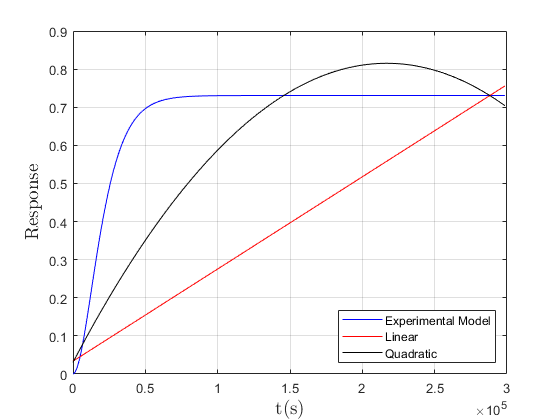

% Times of observation

t = (0.1:1500:3e5)';

% Values of model experiment

y_model = Experiment_Simulation2(model_experiment, t, 0, 1);

% Values of linear model

% - Getting the index of the best round, maximum number of experiments

errors_CE = results_ODoE_CE_lin{n_cases_lin,7};
errors_GA = results_ODoE_GA_lin{n_cases_lin,7};

[~,ind_best_CE] = min(errors_CE);
[~,ind_best_GA] = min(errors_GA);

% - Getting the parameters of the model of this best round

p_rounds_CE = results_ODoE_CE_lin{n_cases_lin,5};
p_rounds_GA = results_ODoE_GA_lin{n_cases_lin,5};

p_best_CE = p_rounds_CE(:,ind_best_CE);
p_best_GA = p_rounds_GA(:,ind_best_GA);

% - Compute the values

X = GeneraX_by_D_ODoE(t,'linear');

y_lin_CE = X*p_best_CE;
y_lin_GA = X*p_best_GA;


% Values of main effects with interactions model

% - Getting the index of the best round, maximum number of experiments

errors_CE = results_ODoE_CE_inter{n_cases_inter,7};
errors_GA = results_ODoE_GA_inter{n_cases_inter,7};

[~,ind_best_CE] = min(errors_CE);
[~,ind_best_GA] = min(errors_GA);

% - Getting the parameters of the model of this best round

p_rounds_CE = results_ODoE_CE_inter{n_cases_inter,5};
p_rounds_GA = results_ODoE_GA_inter{n_cases_inter,5};

p_best_CE = p_rounds_CE(:,ind_best_CE);
p_best_GA = p_rounds_GA(:,ind_best_GA);

% - Compute the values

X = GeneraX_by_D_ODoE(t,'interactions');

y_inter_CE = X*p_best_CE;
y_inter_GA = X*p_best_GA;


% Values of quadratic model

% - Getting the index of the best round, maximum number of experiments

errors_CE = results_ODoE_CE_quad{n_cases_quad,7};
errors_GA = results_ODoE_GA_quad{n_cases_quad,7};

[~,ind_best_CE] = min(errors_CE);
[~,ind_best_GA] = min(errors_GA);

% - Getting the parameters of the model of this best round

p_rounds_CE = results_ODoE_CE_quad{n_cases_quad,5};
p_rounds_GA = results_ODoE_GA_quad{n_cases_quad,5};

p_best_CE = p_rounds_CE(:,ind_best_CE);
p_best_GA = p_rounds_GA(:,ind_best_GA);

% - Compute the values

X = GeneraX_by_D_ODoE(t,'quadratic');

y_quad_CE = X*p_best_CE;
y_quad_GA = X*p_best_GA;


% PLOTS

% CE

figure(5)
plot(t,y_model,'b')
hold on
plot(t,y_lin_CE,'r')
%plot(t,y_inter_CE,'g')
plot(t,y_quad_CE,'k')
hold off
%title("Models achieved vs Model of experimentation, CE algorithm",'Interpreter','latex','FontWeight','bold','FontSize',14)
xlabel("t(s)",'Interpreter','latex','FontWeight','bold','FontSize',14)
ylabel("Response",'Interpreter','latex','FontWeight','bold','FontSize',14)
grid on
legend('Experimental Model','Linear','Quadratic','Location','southeast')

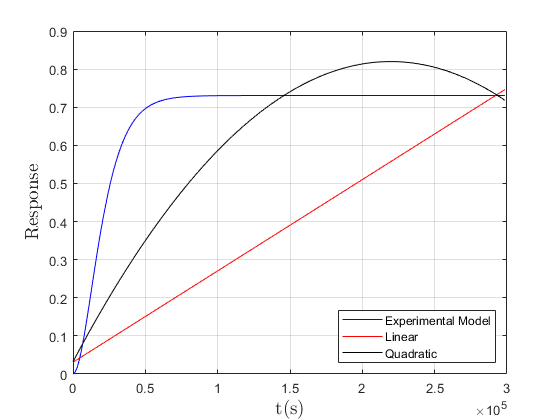


% GA

figure(6)
plot(t,y_model,'b')
hold on
plot(t,y_lin_GA,'r')
%plot(t,y_inter_GA,'g')
plot(t,y_quad_GA,'k')
hold off
%title("Models achieved vs Model of experimentation, GA",'Interpreter','latex','FontWeight','bold','FontSize',14)
xlabel("t(s)",'Interpreter','latex','FontWeight','bold','FontSize',14)
ylabel("Response",'Interpreter','latex','FontWeight','bold','FontSize',14)
grid on
legend('Experimental Model','Linear','Quadratic','Location','southeast')

- Sum of error in each round of experimentation (for one case of number of experiments: n_max)

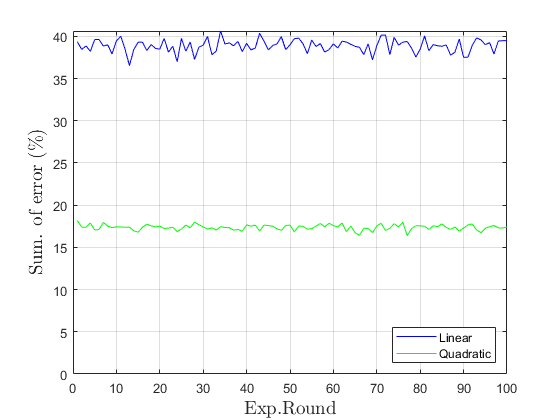

% Load of errors:

errors_CE_lin = results_ODoE_CE_lin{n_cases_lin,7};
errors_CE_inter = results_ODoE_CE_inter{n_cases_inter,7};
errors_CE_quad = results_ODoE_CE_quad{n_cases_quad,7};

errors_GA_lin = results_ODoE_GA_lin{n_cases_lin,7};
errors_GA_inter = results_ODoE_GA_inter{n_cases_inter,7};
errors_GA_quad = results_ODoE_CE_quad{n_cases_quad,7};

% PLOTS

round_exp = 1:n_rounds;

% CE

figure(7)
plot(round_exp,errors_CE_lin,'b')
hold on
%plot(round_exp,errors_CE_inter,'r')
plot(round_exp,errors_CE_quad,'g')
hold off
ylim([0 Inf])
%title("Sum of relative errors in each experiments round (Maximum number of experiments), CE Algorithm",'Interpreter','latex','FontWeight','bold','FontSize',10)
xlabel("Exp.Round",'Interpreter','latex','FontWeight','bold','FontSize',14)
ylabel("Sum. of error (\%)",'Interpreter','latex','FontWeight','bold','FontSize',14)
grid on
legend('Linear','Quadratic','Location','southeast')

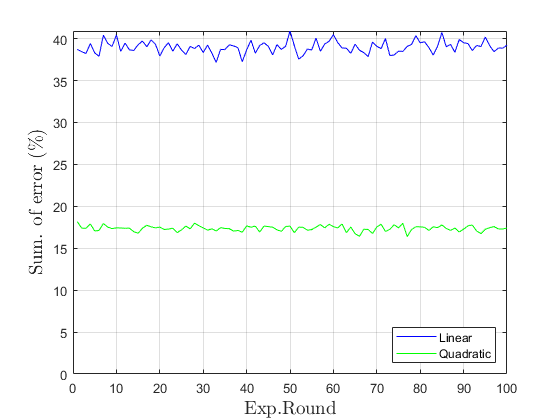



% GA

figure(8)
plot(round_exp,errors_GA_lin,'b')
hold on
%plot(round_exp,errors_GA_inter,'r')
plot(round_exp,errors_GA_quad,'g')
hold off
ylim([0 Inf])
%title("Sum of relative errors in each experiments round (Maximum number of experiments), GA",'Interpreter','latex','FontWeight','bold','FontSize',10)
xlabel("Exp.Round",'Interpreter','latex','FontWeight','bold','FontSize',14)
ylabel("Sum. of error (\%)",'Interpreter','latex','FontWeight','bold','FontSize',14)
grid on
legend('Linear','Quadratic','Location','southeast')

- Mean error of all experimental rounds per number of experiments

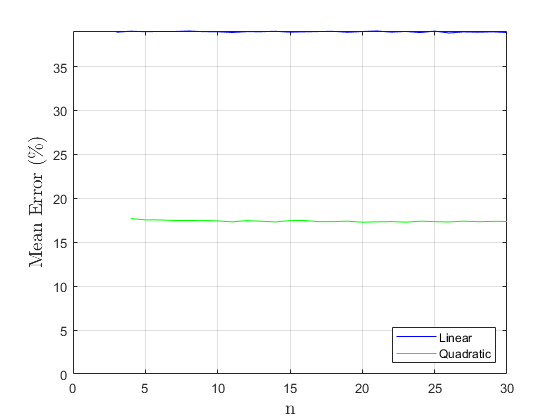

% Experiments cases

experiments_lin = n_min_lin:n_max;
experiments_inter = n_min_inter:n_max;
experiments_quad = n_min_quad:n_max;

% Load of errors:

% Linear

mean_error_CE_lin = zeros(1,n_cases_lin);
mean_error_GA_lin = zeros(1,n_cases_lin);

for index = 1:n_cases_lin
    
    mean_error_CE_lin(index) = results_ODoE_CE_lin{index, 8};
    mean_error_GA_lin(index) = results_ODoE_GA_lin{index, 8};
    
end

% Inter

mean_error_CE_inter = zeros(1,n_cases_inter);
mean_error_GA_inter = zeros(1,n_cases_inter);

for index = 1:n_cases_inter
    
    mean_error_CE_inter(index) = results_ODoE_CE_inter{index, 8};
    mean_error_GA_inter(index) = results_ODoE_GA_inter{index, 8};
    
end

% Quad

mean_error_CE_quad = zeros(1,n_cases_quad);
mean_error_GA_quad = zeros(1,n_cases_quad);

for index = 1:n_cases_quad
    
    mean_error_CE_quad(index) = results_ODoE_CE_quad{index, 8};
    mean_error_GA_quad(index) = results_ODoE_GA_quad{index, 8};
    
end

% PLOTS

% CE

figure(9)
plot(experiments_lin,mean_error_CE_lin,'b')
hold on
%plot(experiments_inter,mean_error_CE_inter,'r')
plot(experiments_quad,mean_error_CE_quad,'g')
hold off
ylim([0 Inf])
%title("Mean error per number of experiments, CE algorithm",'Interpreter','latex','FontWeight','bold','FontSize',10)
xlabel("n",'Interpreter','latex','FontWeight','bold','FontSize',14)
ylabel("Mean Error (\%)",'Interpreter','latex','FontWeight','bold','FontSize',14)
grid on
legend('Linear','Quadratic','Location','southeast')

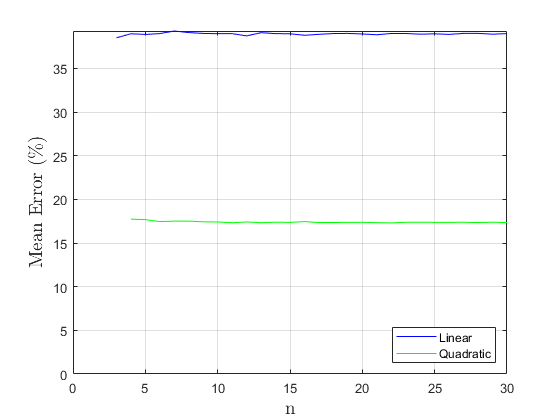


% GA

figure(10)
plot(experiments_lin,mean_error_GA_lin,'b')
hold on
%plot(experiments_inter,mean_error_GA_inter,'r')
plot(experiments_quad,mean_error_GA_quad,'g')
hold off
ylim([0 Inf])
%title("Mean error per number of experiments, GA",'Interpreter','latex','FontWeight','bold','FontSize',10)
xlabel("n",'Interpreter','latex','FontWeight','bold','FontSize',14)
ylabel("Mean Error (\%)",'Interpreter','latex','FontWeight','bold','FontSize',14)
grid on
legend('Linear','Quadratic','Location','southeast')

- Max error of all experimental rounds per number of experiments

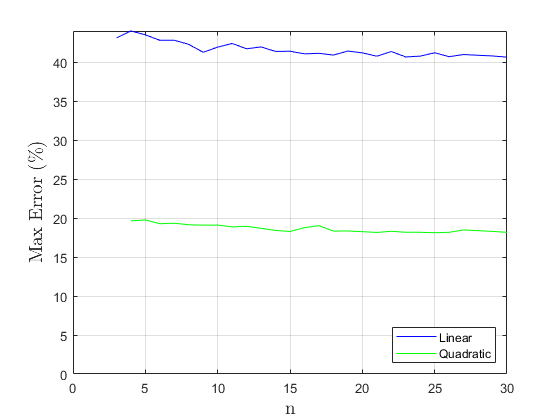

% Load of errors:

% Linear

max_error_CE_lin = zeros(1,n_cases_lin);
max_error_GA_lin = zeros(1,n_cases_lin);

for index = 1:n_cases_lin
    
    max_error_CE_lin(index) = results_ODoE_CE_lin{index, 9};
    max_error_GA_lin(index) = results_ODoE_GA_lin{index, 9};
    
end

% Inter

max_error_CE_inter = zeros(1,n_cases_inter);
max_error_GA_inter = zeros(1,n_cases_inter);

for index = 1:n_cases_inter
    
    max_error_CE_inter(index) = results_ODoE_CE_inter{index, 9};
    max_error_GA_inter(index) = results_ODoE_GA_inter{index, 9};
    
end

% Quad

max_error_CE_quad = zeros(1,n_cases_quad);
max_error_GA_quad = zeros(1,n_cases_quad);

for index = 1:n_cases_quad
    
    max_error_CE_quad(index) = results_ODoE_CE_quad{index, 9};
    max_error_GA_quad(index) = results_ODoE_GA_quad{index, 9};
    
end

% PLOTS

% CE

figure(11)
plot(experiments_lin,max_error_CE_lin,'b')
hold on
%plot(experiments_inter,max_error_CE_inter,'r')
plot(experiments_quad,max_error_CE_quad,'g')
hold off
ylim([0 Inf])
%title("Max error per number of experiments, CE algorithm",'Interpreter','latex','FontWeight','bold','FontSize',10)
xlabel("n",'Interpreter','latex','FontWeight','bold','FontSize',14)
ylabel("Max Error (\%)",'Interpreter','latex','FontWeight','bold','FontSize',14)
grid on
legend('Linear','Quadratic','Location','southeast')

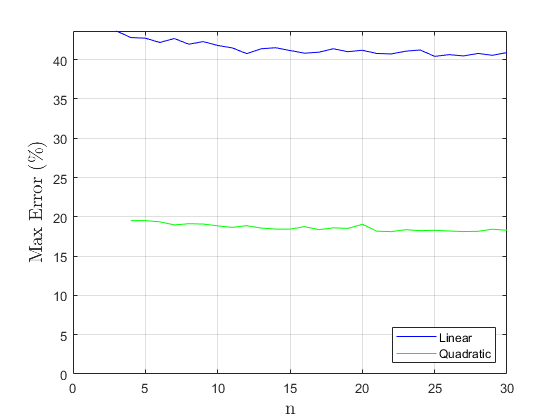


% GA

figure(12)
plot(experiments_lin,max_error_GA_lin,'b')
hold on
%plot(experiments_inter,max_error_GA_inter,'r')
plot(experiments_quad,max_error_GA_quad,'g')
hold off
ylim([0 Inf])
%title("Max error per number of experiments, GA",'Interpreter','latex','FontWeight','bold','FontSize',10)
xlabel("n",'Interpreter','latex','FontWeight','bold','FontSize',14)
ylabel("Max Error (\%)",'Interpreter','latex','FontWeight','bold','FontSize',14)
grid on
legend('Linear','Quadratic','Location','southeast')